# 距离多普勒算法

**算法简介**

在**原始SAR信号空间**中，一个地面目标点的**反射回波数据**占据了一块区域(**多个像素点**)，严重的是，目标点的**展宽扩散**就会污染影响相邻的目标点，造成**散焦**，视觉上就给人模糊不清的感觉。**距离多普勒算法**(RDA)通过距离和方位上的**频域操作**(对原始SAR回波数据进行压缩，从而达到聚焦的目的)，达到了高效的模块化处理要求，同时又具有了一维操作的简便性，RDA算法根据距离和方位上的大尺度时间差异，在两个一维操作之间使用距**离徙动校正**(RCMC)，对距离向和方位向进行了近似的分离处理，使得距离向压缩和方位向压缩可以解耦。

**算法概述**

                         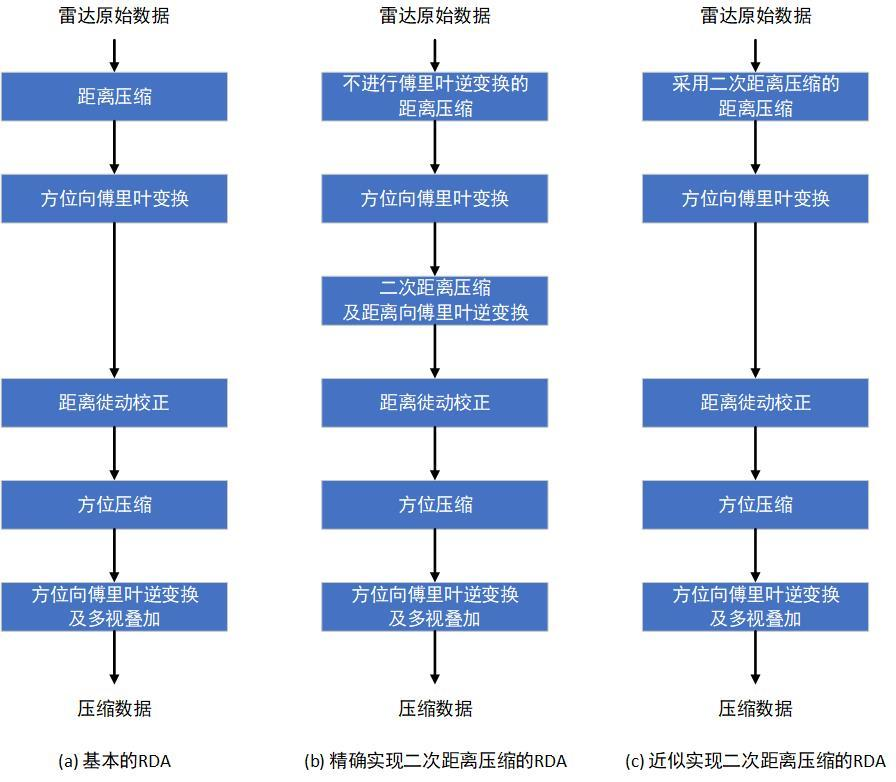

(a)给出的是适合小斜视角及短孔径下的基本RDA处理算法，(b)是斜视处理所需的二次距离压缩改进算法，其中二次距离压缩为二维频域中的精确实现，(c)是二次距离压缩的近似距离频域实现，与(b)相比，其效率较高。

**仿真参数**

**距离向参数：**

                      √ 景中心斜距        $R(\eta_c)$       R_eta_c        20               $km$

                      √ 发射脉冲时宽    $T_r$             Tr                  2.5              $\mu s$

                      √ 距离向调频率    $K_r$             Kr                 20e+12       $Hz/s$

                      √ 距离信号带宽    $B_\omega$            Bw               $|K_r|T_r$          $Hz$

                      √ 距离过采样率    $\alpha_{os,r}$          alpha_os_r   1.2                \

                      √ 距离向采样率    $F_r$             Fr                 $\alpha_{os,r}B_\omega$        $Hz$        

                      √ 距离线采样点数$N_{rg}$            Nrg               320              \

                         距离向分辨率    $\rho_r$             rho_r             2.7              $m$

**方位向参数：**

**                      √ **等效雷达速度    $Vr$            Vr                150                $m/s$

                      √ 电磁传播速度    $c$               c                  3e+8             $m/s$

                      √ 雷达工作频率    $f_0$              f0                 5.3e+9          $Hz$

                      √ 雷达工作波长    $\lambda$              lambda         $c/f_0$              $m$

                      √ 多普勒带宽       $\Delta f_{dop}$        Delta_f_dop  80                 $Hz$

                         目标照射时间    $T_a$            Ta                 **formula**         $s$

                         方位向调频率    $K_a$            Ka                **formula**        $Hz/s$

                      √ 方位过采样率    $\alpha_{os,a}$         alpha_os_a   1.25               \

                     √  方位向采样率    $F_a$            Fa                 $\alpha_{os,a}\Delta f_{dop}$      $Hz$

                      √ 距离线数           $N_{az}$           Naz               256                \

                         方位向分辨率    $\rho_a$            rho_a            1.7                $m$

**方位向参数：**

**                      √ **波束斜视角              $\theta_{sq,c}$   theta_sq_c    3.5&+21.9     $^{\circ}$

                      √ 波束中心穿越时刻    $\eta_c$     t_eta_c          -8.1&-49.7    $s$      

                         
$$\eta_c = -R(\eta_c)\sin\theta_(sq,c)/V_g
           = -R(\eta_c)\sin\theta_(r,c)/V_r$$


                      √ 多普勒中心频率      $f_{\eta_c}$      f_eta_c          320&1975    $Hz$  

                         
$$f_{\eta_c}=2V_s\sin\theta_{sq,c}/\lambda
               =2V_r\sin\theta_{r,c}/\lambda$$


由于是以上参数是机载C波段雷达仿真参数，故$\theta_{r,c}=\theta_{sq,c}$，$V_r=V_s=V_g$。

目标照射时间公式为：$T_a=0.886\frac{\lambda R(\eta_c)}{L_aV_g\cos\theta_{r,c}}$，方位向调频率公式为：$K_a=\frac{2V_r^2\cos^2\theta_{r,c}}{\lambda R(\eta_c)}$。除此之外，雷达到目标的最短距离为：$R_0=R(\eta_c)\cos\theta_{r,c}$，雷达的方位向3dB波束宽度为：$\theta_{bw}=\frac{\lambda\Delta f_{dop}}{2V_s\cos\theta_{r,c}}=0.886\frac{\lambda}{L_a}$，则实际天线长度为：$L_a=0.886\frac{2V_s\cos\theta_{r,c}}{\Delta f_{dop}}$。我们还可以得到在无孔径加权的情况下的距离分辨率$\rho_r=\frac{c}{2B_\omega}$和方位分辨率$\rho_a=\frac{L_a}{2}$。

**雷达原始数据**


$$s_0(\tau,\eta)=A_0
                        \omega_r\left(\tau-\frac{2R(\eta)}{c}\right)
                        \omega_a(\eta-\eta_c)
                        \exp\left\{ -j4\pi\frac{f_0R(\eta)}{c} \right\}
                        \exp\left\{ j\pi K_r\left(\tau-\frac{2R(\eta)}{c}\right)^2 \right\}$$


$T_a=0.886\frac{\lambda R(\eta_c)}{L_aV_g\cos\theta_{r,c}}$，$K_a=\frac{2V_r^2\cos^2\theta_{r,c}}{\lambda R(\eta_c)}$，$R(\eta)=\sqrt{R_0^2+V_r^2\eta^2}$，

$\omega_r\left(\tau-\frac{2R(\eta)}{c}\right)=rect\left(\frac{\tau-2R(\eta)/c}{T_r}\right)$，$\omega_a(\eta-\eta_c)=sinc^2\left[0.886\frac{\theta_{r,c}}{\theta_{bw}}\right]=sinc^2\left[0.886\frac{\arctan(V_g(\eta-\eta_c)/R_0)}{\theta_{bw}}\right]$

                               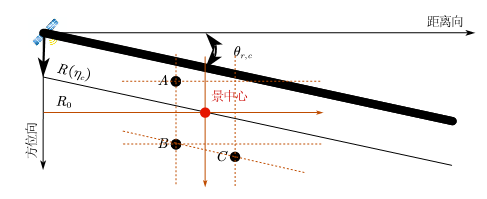

$\bullet$ 距离向和方位向的观测中心选取：距离向观测时间中心应该选为$2R(\eta_c)/c$，方位向观测时间中心应该选为$\eta_c$。这是因为雷达回波数据都以这两个时刻为中心分布，如此方能在原始雷达图像中观测到目标点数据。

$\bullet$ 目标点位置的设置：目标点的波束中心穿越时刻应该与景中心的波束中心穿越时刻相近，即目标点的波束中心穿越时刻斜距应该与景中心斜距相近，这样我们才能在有效的观测范围内观测到全部目标点。

$\bullet$ 距离徙动校正时距离向的观测中心选取：距离轴的中心应该选为$R_0=R(\eta_c)\cos\theta_{r,c}$。这是因为距离徙动校正后，目标数据点都会移动到自己的最近斜距处，若仍以$R(\eta_c)$作为距离轴的中心，则会导致距离徙动校正错误。

clc
clear
close all
%% 参数设置
%  已知参数--》距离向参数
R_eta_c = 20e+3;                % 景中心斜距
Tr = 2.5e-6;                    % 发射脉冲时宽
Kr = 20e+12;                    % 距离向调频率
alpha_os_r = 1.2;               % 距离过采样率
Nrg = 320;                      % 距离线采样点数
%  计算参数--》距离向参数
Bw = abs(Kr)*Tr;                % 距离信号带宽
Fr = alpha_os_r*Bw;             % 距离向采样率
Nr = round(Fr*Tr);              % 距离采样点数(脉冲序列长度)
%  已知参数--》方位向参数
c = 3e+8;                       % 电磁传播速度
Vr = 150;                       % 等效雷达速度
Vs = Vr;                        % 卫星平台速度
Vg = Vr;                        % 波束扫描速度
f0 = 5.3e+9;                    % 雷达工作频率
Delta_f_dop = 80;               % 多普勒带宽
alpha_os_a = 1.25;              % 方位过采样率
Naz = 256;                      % 距离线数
theta_r_c = +45.9*pi/180;       % 波束斜视角
%  计算参数--》方位向参数
lambda = c/f0;                  % 雷达工作波长
t_eta_c = -R_eta_c*sin(theta_r_c)/Vr;
                                % 波束中心穿越时刻
f_eta_c = 2*Vr*sin(theta_r_c)/lambda;
                                % 多普勒中心频率
La = 0.886*2*Vs*cos(theta_r_c)/Delta_f_dop;               
                                % 实际天线长度
Fa = alpha_os_a*Delta_f_dop;    % 方位向采样率
Ta = 0.886*lambda*R_eta_c/(La*Vg*cos(theta_r_c));
                                % 目标照射时间
R0 = R_eta_c*cos(theta_r_c);    % 最短斜距
Ka = 2*Vr^2*cos(theta_r_c)^2/lambda/R0;              
                                % 方位向调频率
theta_bw = 0.886*lambda/La;     % 方位向3dB波束宽度
theta_syn = Vs/Vg*theta_bw;     % 合成角宽度
Ls = R_eta_c*theta_syn;         % 合成孔径长度
%  参数计算
rho_r = c/(2*Fr);               % 距离向分辨率
rho_a = La/2;                   % 距离向分辨率
Trg = Nrg/Fr;                   % 发射脉冲时宽
Taz = Naz/Fa;                   % 目标照射时间
d_t_tau = 1/Fr;                 % 距离采样时间间隔
d_t_eta = 1/Fa;                 % 方位采样时间间隔
d_f_tau = Fr/Nrg;               % 距离采样频率间隔    
d_f_eta = Fa/Naz;               % 方位采样频率间隔

%% 目标设置
%  设置目标点相对于景中心之间的距离
A_r =   0; A_a =   0;                                   % A点位置
B_r = -50; B_a = -50;                                   % B点位置
C_r = -50; C_a = +50;                                   % C点位置
D_r = +50; D_a = C_a + (D_r-C_r)*tan(theta_r_c);        % D点位置
%  得到目标点相对于景中心的位置坐标
A_x = R0 + A_r; A_Y = A_a;                              % A点坐标
B_x = R0 + B_r; B_Y = B_a;                              % B点坐标
C_x = R0 + C_r; C_Y = C_a;                              % C点坐标
D_x = R0 + D_r; D_Y = D_a;                              % D点坐标
NPosition = [A_x,A_Y;
             B_x,B_Y;
             C_x,C_Y;
             D_x,D_Y;];                                 % 设置数组
fprintf( 'A点坐标为[%+3.3f，%+3.3f]km\n', NPosition(1,1)/1e3, NPosition(1,2)/1e3 );

A点坐标为[+13.918，+0.000]km


fprintf( 'B点坐标为[%+3.3f，%+3.3f]km\n', NPosition(2,1)/1e3, NPosition(2,2)/1e3 );

B点坐标为[+13.868，-0.050]km


fprintf( 'C点坐标为[%+3.3f，%+3.3f]km\n', NPosition(3,1)/1e3, NPosition(3,2)/1e3 );

C点坐标为[+13.868，+0.050]km


fprintf( 'D点坐标为[%+3.3f，%+3.3f]km\n', NPosition(4,1)/1e3, NPosition(4,2)/1e3 );

D点坐标为[+13.968，+0.153]km


%  得到目标点的波束中心穿越时刻
Ntarget = 4;
Tar_t_eta_c = zeros(1,Ntarget);
for i = 1 : Ntarget
    DeltaX = NPosition(i,2) - NPosition(i,1)*tan(theta_r_c);
    Tar_t_eta_c(i) = DeltaX/Vs;
end
%  得到目标点的绝对零多普勒时刻
Tar_t_eta_0 = zeros(1,Ntarget);
for i = 1 : Ntarget
    Tar_t_eta_0(i) = NPosition(i,2)/Vr;
end

%% 变量设置
%  时间变量 以景中心的零多普勒时刻作为方位向零点
t_tau = (-Trg/2:d_t_tau:Trg/2-d_t_tau) + 2*R_eta_c/c;   % 距离时间变量
t_eta = (-Taz/2:d_t_eta:Taz/2-d_t_eta) + t_eta_c;       % 方位时间变量
%{
t_tau = (-Nrg/2:Nrg/2-1)/Fr + 2*R_eta_c/c;              % 距离时间变量
t_eta = (-Naz/2:Naz/2-1)/Fa + t_eta_c;                  % 方位时间变量
%}
%{
t_tau = linspace(-Nrg/2,Nrg/2-1,Nrg)/Fr + 2*R_eta_c/c;  % 距离时间变量
t_eta = linspace(-Naz/2:Naz/2-1,Naz)/Fa + t_eta_c;      % 方位时间变量
%}
%  长度变量
r_tau = (t_tau*c/2)*cos(theta_r_c);                     % 距离长度变量
%{
r_tau = ((-Trg/2:d_t_tau:Trg/2-d_t_tau)*c/2)*cos(theta_r_c) + R0;
                                                        % 距离长度变量
%}                                                      
%{
r_tau = ((-Nrg/2:Nrg/2-1)*rho_r)*cos(theta_r_c) + R0;   % 距离长度变量
%}                                                      
%{
r_tau = (linspace(-Nrg/2,Nrg/2-1,Nrg)*rho_r)*cos(theta_r_c) + R0;
                                                        % 距离长度变量
%}                                                      
%  频率变量 
f_tau = fftshift(-Fr/2:d_f_tau:Fr/2-d_f_tau);           % 距离频率变量
f_tau = f_tau - round((f_tau-0)/Fr)*Fr;                 % 距离频率变量(可观测频率)                          
%{
f_tau = fftshift((-Nrg/2:Nrg/2-1)*Fr/Nrg);              % 距离频率变量
f_tau = f_tau - round((f_tau-0)/Fr)*Fr;                 % 距离频率变量(可观测频率)
%} 
%{
f_tau = fftshift(linspace(-Nrg/2,Nrg/2-1,Nrg)*Fr/Nrg);  % 距离频率变量
f_tau = f_tau - round((f_tau-0)/Fr)*Fr;                 % 距离频率变量(可观测频率)
%}
f_eta = fftshift(-Fa/2:d_f_eta:Fa/2-d_f_eta);           % 方位频率变量
f_eta = f_eta - round((f_eta-f_eta_c)/Fa)*Fa;           % 方位频率变量(可观测频率)
%{
M_amb = round(f_eta_c/Fa);                              % 多普勒中心频率整数部分
N_amb = f_eta_c/Fa-round(f_eta_c/Fa);                   % 多普勒中心频率小数部分
if (N_amb < 0.25)
    f_eta = M_amb*Fa + fftshift((-Naz/2:Naz/2-1)*Fa/Naz);
else
    if (N_amb > 0.75)
        f_eta = M_amb*Fa + Fa/2 + fftshift((0:Naz-1)*Fa/Naz);
    else
        f_eta = M_amb*Fa + fftshift((0:Naz-1)*Fa/Naz);
    end
end
N_middle = find(abs(f_eta-f_eta_c) <= Fa/Naz/2);
%}
%{
f_eta = fftshift((-Naz/2:Naz/2-1)*Fa/Naz);              % 方位频率变量
f_eta = f_eta - round((f_eta-f_eta_c)/Fa)*Fa;           % 方位频率变量(可观测频率)
%} 
%{
f_eta = fftshift(linspace(-Naz/2,Naz/2-1,Naz)*Fa/Naz);  % 脉冲频率变量
f_eta = f_eta - round((f_eta-f_eta_c)/Fa)*Fa;           % 方位频率变量(可观测频率)
%}
%% 坐标设置 
%{
[X,Y] = meshgrid(x,y)是基于向量x和向量y中包含的坐标返回二维网络坐标。
 X是一个矩阵，每一行是x的一个副本；
 Y是一个矩阵，每一列是y的一个副本；
 坐标X和Y表示的网络有length(y)个行和length(x)个列。
%}     
%  以距离时间为X轴，方位时间为Y轴
[t_tauX,t_etaY] = meshgrid(t_tau,t_eta);                % 设置距离时域-方位时域二维网络坐标
%  以距离长度为X轴，方位频率为Y轴                                                                                                            
[r_tauX,f_etaY] = meshgrid(r_tau,f_eta);                % 设置距离时域-方位频域二维网络坐标
%  以距离频率为X轴，方位频率为Y轴                                                                                                            
[f_tau_X,f_eta_Y] = meshgrid(f_tau,f_eta);              % 设置频率时域-方位频域二维网络坐标

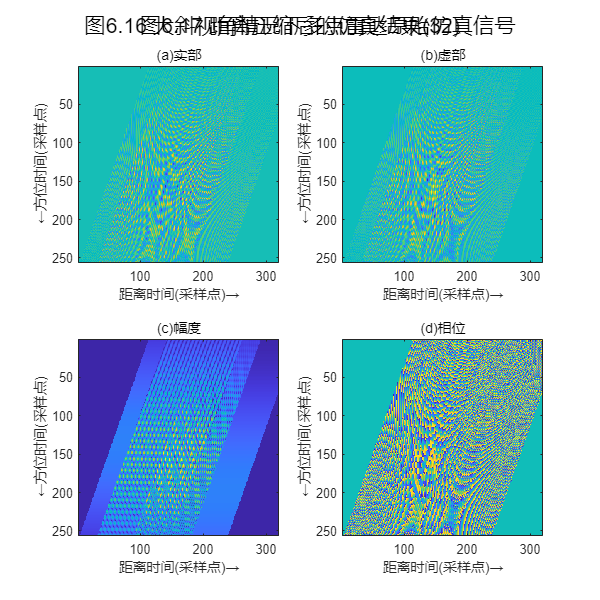

%% 信号设置--》原始回波信号                                                        
st_tt = zeros(Naz,Nrg);
for i = 1 : Ntarget
    %  计算目标点的瞬时斜距
    R_eta = sqrt( NPosition(i,1)^2 +...
                  Vr^2*(t_etaY-Tar_t_eta_0(i)).^2 ); 
    %{
    R_eta = NPosition(i,1) + Vr^2*t_etaY.^2/(2*NPosition(i,1));   
    %}
    %  后向散射系数幅度
    A0 = [1,1,1,1]*exp(+1j*0);   
    %  距离向包络
    wr = (abs(t_tauX-2*R_eta/c) <= Tr/2);                               
    %{
    距离向包络为矩形窗，因此可以观察到信号幅度图在距离向是均匀的，
    但是严格的矩形窗也导致了幅度图和相位图在左右两侧均出现0值区域。
    %}
    %  方位向包络
    wa = sinc(0.886*atan(Vg*(t_etaY-Tar_t_eta_c(i))/NPosition(i,1))/theta_bw).^2;      
    %{
    方位向包络为sinc^2()的形式，因此可以观察到信号幅度图在方位向上
    中心最强，而两侧的强度以sinc^2()的形式衰减。
    %}
    %  接收信号叠加
    st_tt_tar = A0(i)*wr.*wa.*exp(-1j*4*pi*f0*R_eta/c)...
                            .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2); 
    %{
    srt_tt_tar = A0(i)*wr.*wa.*exp(-1j*4*pi*R0/lambda)...
                             .*exp(-1j*pi*Ka*t_eta_Y.^2)...
                             .*exp(+1j*pi*Kr*(t_tauX-2*R_eta/c).^2);
    %}                                                          
    st_tt = st_tt + st_tt_tar;  
end
%  绘图
H1 = figure();
set(H1,'position',[100,100,600,600]);                    
subplot(221),imagesc( real(st_tt))             
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
subplot(222),imagesc( imag(st_tt))
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)虚部')
subplot(223),imagesc(  abs(st_tt)) 
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(c)幅度')
subplot(224),imagesc(angle(st_tt))
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(d)相位')
sgtitle('图6.16 大斜视角情况下多点雷达原始仿真信号','Fontsize',16,'color','k')

%% 信号设置--》一次距离压缩
%  变量设置
dt = Tr/Nr;                                             % 脉冲时间间隔
ttau = -Tr/2:dt:Tr/2-dt;                                % 脉冲时间变量
%{
ttau = (-Nr/2:Nr/2-1)/Fr;                               % 脉冲时间变量
%}
%{
ttau = linspace(-Nr/2,Nr/2,Nr)/Fr;                      % 脉冲时间变量
%}
%  计算滤波器
%  信号变换-->方式一：复制脉冲，时间反褶后取复共轭，补零DFT得到频域匹配滤波器
%  加窗函数
% window_1 = kaiser(Nr,2.5)';                             % 时域窗
% Window_1 = fftshift(window_1);                          % 频域窗
% hrt_1 = (abs(ttau)<=Tr/2).*exp(+1j*pi*Kr*ttau.^2);      % 复制脉冲
% hrt_window_1 = Window_1.*hrt_1;                         % 加窗
% Hrf_1 = repmat(fft(conj(fliplr(hrt_window_1)),Nrg,2),[Naz,1]);                        
%  信号变换-->方式二：复制脉冲，补零DFT，取复共轭得到频域匹配滤波器无时间反褶
% window_2 = kaiser(Nr,2.5)';                             % 时域窗
% Window_2 = fftshift(window_2);                          % 频域窗
% hrt_2 = (abs(ttau)<=Tr/2).*exp(+1j*pi*Kr*ttau.^2);      % 复制脉冲
% hrt_window_2 = Window_2.*hrt_2;                         % 加窗
% Hrf_2 = repmat(conj(fft(hrt_window_2,Nrg,2)),[Naz,1]);                   
%  信号变换-->方式三：根据脉冲频谱特性直接在频域生成频域匹配滤波器
window_3 = kaiser(Nrg,2.5)';                            % 时域窗
Window_3 = fftshift(window_3);                          % 频域窗
% Window_3 = repmat([Window_3(1:ceil(Nr/2)),zeros(1,Nrg-Nr),Window_3(ceil(Nr/2)+1:Nr)],[256,1]);
Hrf_3 = (abs(f_tau_X)<=Bw/2).*Window_3.*exp(+1j*pi*f_tau_X.^2/Kr);  
%  匹配滤波
Sf_ft = fft(st_tt,Nrg,2);
% Srf_ft_1 = Sf_ft.*Hrf_1;
% srt_tt_1 = ifft(Srf_ft_1,Nrg,2);
% Srf_ft_2 = Sf_ft.*Hrf_2;
% srt_tt_2 = ifft(Srf_ft_2,Nrg,2);
Srf_ft_3 = Sf_ft.*Hrf_3;
srt_tt_3 = ifft(Srf_ft_3,Nrg,2);
% %  绘图
% H2 = figure();
% set(H2,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(srt_tt_1))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
% subplot(122),imagesc( abs(srt_tt_1))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
% sgtitle('图6.4 方式一得到一次距离压缩后的仿真结果','Fontsize',16,'color','k')
% %  绘图
% H3 = figure();
% set(H3,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(srt_tt_2))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
% subplot(122),imagesc( abs(srt_tt_2))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
% sgtitle('图6.4 方式二得到一次距离压缩后的仿真结果','Fontsize',16,'color','k')
% %  绘图
% H4 = figure();
% set(H4,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(srt_tt_3))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
% subplot(122),imagesc( abs(srt_tt_3))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
% sgtitle('图6.4 方式三得到一次距离压缩后的仿真结果','Fontsize',16,'color','k')

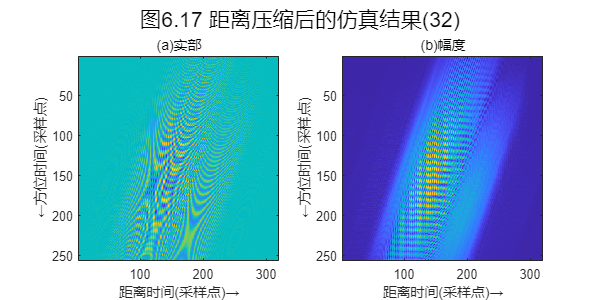

%% 信号设置--》二次距离压缩
Drd0 = sqrt(1-lambda^2*f_eta_c^2/(4*Vr^2));             % 距离多普勒域中的徙动因子
Ksrc = 2*Vr^2*f0^3*Drd0^3/(c*R0*f_eta_c^2);             % 距离补偿调频率
Hsrcf = exp(-1j*pi*f_tau_X.^2/Ksrc);  
%  信号变换-->方式二
Srf_ft_32 = Sf_ft.*Hrf_3;
Srf_ff_32 = fft(Srf_ft_32,Naz,1);
Soutf_ff_32 = Srf_ff_32.*Hsrcf;
srt_tt_32 = ifft2(Soutf_ff_32);
%  信号变换-->方式三，一次距离压缩和二次距离压缩的合并操作
Km = Kr*Ksrc/(Ksrc-Kr);                                 
Hmf_3 = Window_3.*exp(+1j*pi*f_tau_X.^2/Km);
Srf_ft_33 = Sf_ft.*Hmf_3;
srt_tt_33 = ifft(Srf_ft_33,Nrg,2);
%  绘图
H5 = figure();
set(H5,'position',[100,100,600,300]); 
subplot(121),imagesc(real(srt_tt_32))
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
subplot(122),imagesc( abs(srt_tt_32))
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
sgtitle('图6.17 距离压缩后的仿真结果(32)','Fontsize',16,'color','k')

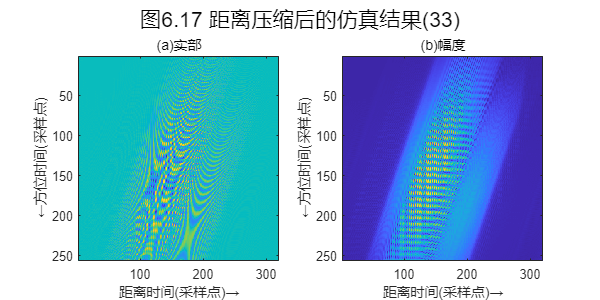

%  绘图
H5 = figure();
set(H5,'position',[100,100,600,300]); 
subplot(121),imagesc(real(srt_tt_33))
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
subplot(122),imagesc( abs(srt_tt_33))
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
sgtitle('图6.17 距离压缩后的仿真结果(33)','Fontsize',16,'color','k')

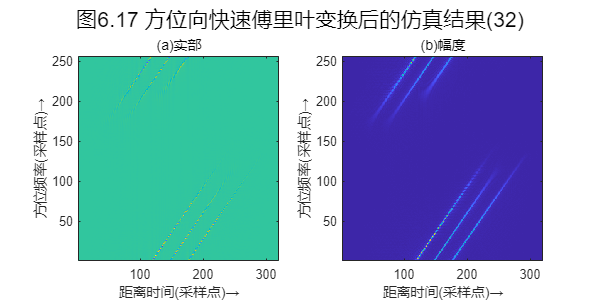

%% 信号设置--》方位向傅里叶变换
% Saf_tf_1 = fft(srt_tt_1,Naz,1);
% Saf_tf_2 = fft(srt_tt_2,Naz,1);
Saf_tf_32 = fft(srt_tt_32,Naz,1);
Saf_tf_33 = fft(srt_tt_33,Naz,1);
% %  绘图
% H6 = figure();
% set(H6,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(Saf_tf_1)),set(gca,'YDir','normal')
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(a)实部')
% subplot(122),imagesc( abs(Saf_tf_1)),set(gca,'YDir','normal')
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(b)幅度')
% sgtitle('图6.5 方位向快速傅里叶变换后的仿真结果','Fontsize',16,'color','k')
% %  绘图
% H7 = figure();
% set(H7,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(Saf_tf_2)),set(gca,'YDir','normal')
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(a)实部')
% subplot(122),imagesc( abs(Saf_tf_2)),set(gca,'YDir','normal')
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(b)幅度')
% sgtitle('图6.5 方位向快速傅里叶变换后的仿真结果','Fontsize',16,'color','k')
%  绘图
H8 = figure();
set(H8,'position',[100,100,600,300]); 
subplot(121),imagesc(real(Saf_tf_32)),set(gca,'YDir','normal')
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(a)实部')
subplot(122),imagesc( abs(Saf_tf_32)),set(gca,'YDir','normal')
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(b)幅度')
sgtitle('图6.17 方位向快速傅里叶变换后的仿真结果(32)','Fontsize',16,'color','k')

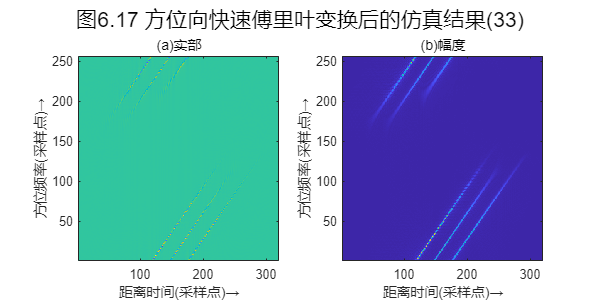

%  绘图
H9 = figure();
set(H9,'position',[100,100,600,300]); 
subplot(121),imagesc(real(Saf_tf_33)),set(gca,'YDir','normal')
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(a)实部')
subplot(122),imagesc( abs(Saf_tf_33)),set(gca,'YDir','normal')
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(b)幅度')
sgtitle('图6.17 方位向快速傅里叶变换后的仿真结果(33)','Fontsize',16,'color','k')

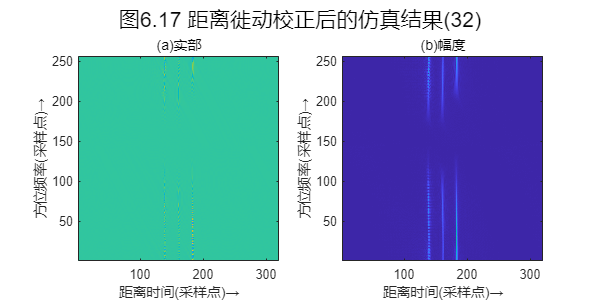

%% 信号设置--》距离徙动校正
Drd = sqrt(1-lambda^2*f_etaY.^2/(4*Vr^2));              % 距离多普勒域中的徙动因子
RCM = r_tauX./Drd-r_tauX;                               % 需要校正的距离徙动量
RCM = R0 + RCM - R_eta_c;                               % 将距离徙动量转换到原图像坐标系中
offset = RCM/rho_r;                                     % 将距离徙动量转换为距离单元偏移量
%  计算插值系数表
x_tmp = repmat(-4:3,[16,1]);                            % 插值长度                          
x_tmp = x_tmp + repmat(((1:16)/16).',[1,8]);            % 量化位移
hx = sinc(x_tmp);                                       % 生成插值核
kwin = repmat(kaiser(8,2.5).',[16,1]);                  % 加窗
hx = kwin.*hx;
hx = hx./repmat(sum(hx,2),[1,8]);                       % 核的归一化
%  插值表校正
% Srcmf_tf_1 = zeros(Naz,Nrg);
% Srcmf_tf_2 = zeros(Naz,Nrg);
Srcmf_tf_32 = zeros(Naz,Nrg);
Srcmf_tf_33 = zeros(Naz,Nrg);
for a_tmp = 1 : Naz
    for r_tmp = 1 : Nrg
        offset_ceil = ceil(offset(a_tmp,r_tmp));
        offset_frac = round((offset_ceil - offset(a_tmp,r_tmp)) * 16);
        if offset_frac == 0
%            Srcmf_tf_1(a_tmp,r_tmp) = Saf_tf_1(a_tmp,ceil(mod(r_tmp+offset_ceil-0.1,Nrg))); 
%            Srcmf_tf_2(a_tmp,r_tmp) = Saf_tf_2(a_tmp,ceil(mod(r_tmp+offset_ceil-0.1,Nrg))); 
           Srcmf_tf_32(a_tmp,r_tmp) = Saf_tf_32(a_tmp,ceil(mod(r_tmp+offset_ceil-0.1,Nrg))); 
           Srcmf_tf_33(a_tmp,r_tmp) = Saf_tf_33(a_tmp,ceil(mod(r_tmp+offset_ceil-0.1,Nrg))); 
        else
%            Srcmf_tf_1(a_tmp,r_tmp) = Saf_tf_1(a_tmp,ceil(mod((r_tmp+offset_ceil-4:r_tmp+offset_ceil+3)-0.1,Nrg)))*hx(offset_frac,:).';
%            Srcmf_tf_2(a_tmp,r_tmp) = Saf_tf_2(a_tmp,ceil(mod((r_tmp+offset_ceil-4:r_tmp+offset_ceil+3)-0.1,Nrg)))*hx(offset_frac,:).';
           Srcmf_tf_32(a_tmp,r_tmp) = Saf_tf_32(a_tmp,ceil(mod((r_tmp+offset_ceil-4:r_tmp+offset_ceil+3)-0.1,Nrg)))*hx(offset_frac,:).';
           Srcmf_tf_33(a_tmp,r_tmp) = Saf_tf_33(a_tmp,ceil(mod((r_tmp+offset_ceil-4:r_tmp+offset_ceil+3)-0.1,Nrg)))*hx(offset_frac,:).';
        end
    end
end
% %  插值函数校正
% R = 8;                                                % 插值核的长度 
% kwin = kaiser(R,2.5)';                                % 加窗
% offset_ceil = ceil(offset);
% % Srcmf_tf_1 = zeros(Naz,Nrg);
% % Srcmf_tf_2 = zeros(Naz,Nrg);
% Srcmf_tf_32 = zeros(Naz,Nrg);
% Srcmf_tf_33 = zeros(Naz,Nrg);
% for a_tmp = 1 : Naz
%     for r_tmp = 1 : Nrg
%         kernel = kwin.*sinc((offset(a_tmp,r_tmp)-offset_ceil(a_tmp,r_tmp))-(-R/2:1:R/2-1));
%         points = r_tmp + offset_ceil(a_tmp,r_tmp) + (-R/2:1:R/2-1);
%         kernel = kernel(points>0 & points<=Nrg);      % 避免索引超出范围
%         points = points(points>0 & points<=Nrg);      % 避免索引超出范围
%         kernal = kernel./sum(kernel);                 % 核的归一化
%         % 插值
% %         Srcmf_tf_1(a_tmp,r_tmp) = Saf_tf_1(a_tmp,points)*kernel';
% %         Srcmf_tf_2(a_tmp,r_tmp) = Saf_tf_2(a_tmp,points)*kernel';
%         Srcmf_tf_32(a_tmp,r_tmp) = Saf_tf_32(a_tmp,points)*kernel';
%         Srcmf_tf_33(a_tmp,r_tmp) = Saf_tf_33(a_tmp,points)*kernel';
%     end
% end
% %  绘图
% H10 = figure();
% set(H10,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(Srcmf_tf_1)),set(gca,'YDir','normal')
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(a)实部')
% subplot(122),imagesc( abs(Srcmf_tf_1)),set(gca,'YDir','normal')
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(b)幅度')
% sgtitle('图6.9 距离徙动校正后的仿真结果','Fontsize',16,'color','k')
% %  绘图
% H11 = figure();
% set(H11,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(Srcmf_tf_2)),set(gca,'YDir','normal')
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(a)实部')
% subplot(122),imagesc( abs(Srcmf_tf_2)),set(gca,'YDir','normal')
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(b)幅度')
% sgtitle('图6.9 距离徙动校正后的仿真结果','Fontsize',16,'color','k')
%  绘图
H12 = figure();
set(H12,'position',[100,100,600,300]); 
subplot(121),imagesc(real(Srcmf_tf_32)),set(gca,'YDir','normal')
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(a)实部')
subplot(122),imagesc( abs(Srcmf_tf_32)),set(gca,'YDir','normal')
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(b)幅度')
sgtitle('图6.17 距离徙动校正后的仿真结果(32)','Fontsize',16,'color','k')

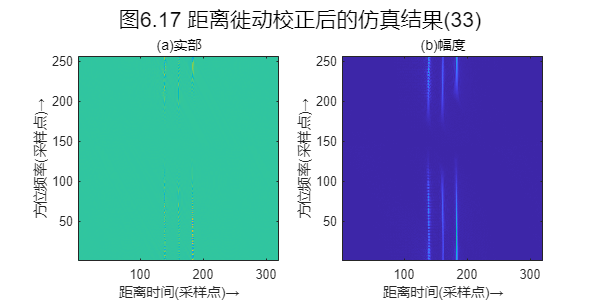

%  绘图
H13 = figure();
set(H13,'position',[100,100,600,300]); 
subplot(121),imagesc(real(Srcmf_tf_33)),set(gca,'YDir','normal')
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(a)实部')
subplot(122),imagesc( abs(Srcmf_tf_33)),set(gca,'YDir','normal')
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('方位频率(采样点)→'),title('(b)幅度')
sgtitle('图6.17 距离徙动校正后的仿真结果(33)','Fontsize',16,'color','k')

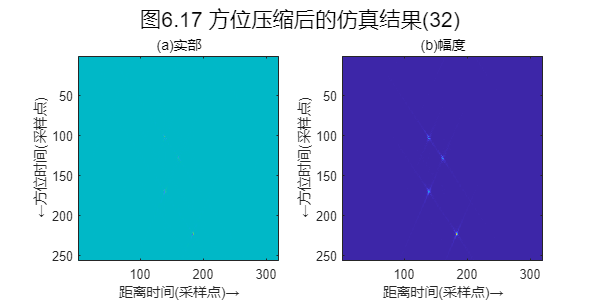

%% 信号设置--》方位压缩
%  计算滤波器
Haf = exp(+1j*4*pi*f0*r_tauX.*Drd/c);
Haf_offset = exp(-1j*2*pi*f_etaY.*t_eta_c);
%  匹配滤波
% Soutf_tf_1 = Srcmf_tf_1.*Haf;
% soutt_tt_1 = ifft(Soutf_tf_1,Naz,1);
% Soutf_tf_2 = Srcmf_tf_2.*Haf;
% soutt_tt_2 = ifft(Soutf_tf_2,Naz,1);
Soutf_tf_32 = Srcmf_tf_32.*Haf.*Haf_offset;
soutt_tt_32 = ifft(Soutf_tf_32,Naz,1);
Soutf_tf_33 = Srcmf_tf_33.*Haf.*Haf_offset;
soutt_tt_33 = ifft(Soutf_tf_33,Naz,1);
% %  绘图
% H14 = figure();
% set(H14,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(soutt_tt_1))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
% subplot(122),imagesc( abs(soutt_tt_1))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
% sgtitle('图6.9 方位压缩后的仿真结果','Fontsize',16,'color','k')
% %  绘图
% H15 = figure();
% set(H15,'position',[100,100,600,300]); 
% subplot(121),imagesc(real(soutt_tt_2))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
% subplot(122),imagesc( abs(soutt_tt_2))
% %  axis([0 Naz,0 Nrg])
% xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
% sgtitle('图6.9 方位压缩后的仿真结果','Fontsize',16,'color','k')
%  绘图
H16 = figure();
set(H16,'position',[100,100,600,300]); 
subplot(121),imagesc(real(soutt_tt_32))
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
subplot(122),imagesc( abs(soutt_tt_32))
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
sgtitle('图6.17 方位压缩后的仿真结果(32)','Fontsize',16,'color','k')

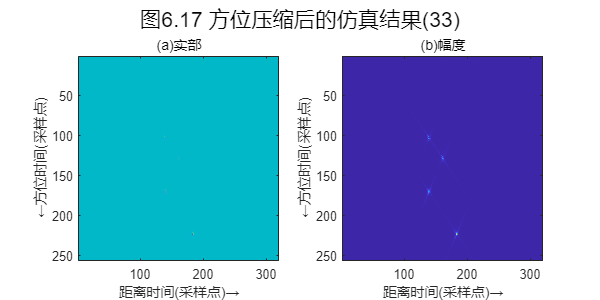

%  绘图
H17 = figure();
set(H17,'position',[100,100,600,300]); 
subplot(121),imagesc(real(soutt_tt_33))
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(a)实部')
subplot(122),imagesc( abs(soutt_tt_33))
%  axis([0 Naz,0 Nrg])
xlabel('距离时间(采样点)→'),ylabel('←方位时间(采样点)'),title('(b)幅度')
sgtitle('图6.17 方位压缩后的仿真结果(33)','Fontsize',16,'color','k')


% [IRW, PSLR, ISLR] = analyze_IR(s, true)

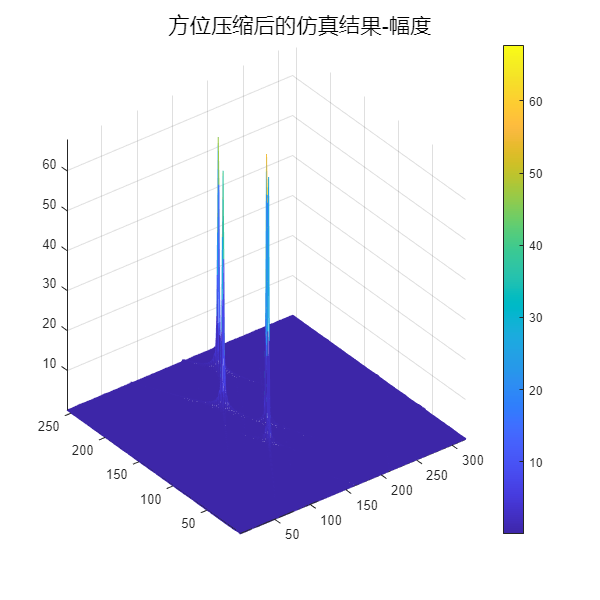

% %  绘图
% H18 = figure();
% set(H18,'position',[100,100,600,600]); 
% mesh(real(soutt_tt_32)),colorbar,axis tight
% sgtitle('方位压缩后的仿真结果-实部','Fontsize',16,'color','k')
% %  绘图
% H19 = figure();
% set(H19,'position',[100,100,600,600]); 
% mesh(imag(soutt_tt_32)),colorbar,axis tight
% sgtitle('方位压缩后的仿真结果-虚部','Fontsize',16,'color','k')
%  绘图
% H20 = figure();
% set(H20,'position',[100,100,600,600]); 
% mesh( abs(soutt_tt_32)),colorbar,axis tight
% sgtitle('方位压缩后的仿真结果-幅度','Fontsize',16,'color','k')
% %  绘图
% H21 = figure();
% set(H21,'position',[100,100,600,600]); 
% mesh(real(soutt_tt_33)),colorbar,axis tight
% sgtitle('方位压缩后的仿真结果-实部','Fontsize',16,'color','k')
% %  绘图
% H22 = figure();
% set(H22,'position',[100,100,600,600]); 
% mesh(imag(soutt_tt_33)),colorbar,axis tight
% sgtitle('方位压缩后的仿真结果-虚部','Fontsize',16,'color','k')
%  绘图
H23 = figure();
set(H23,'position',[100,100,600,600]); 
mesh( abs(soutt_tt_33)),colorbar,axis tight
sgtitle('方位压缩后的仿真结果-幅度','Fontsize',16,'color','k')